K0 = 4.4;
T0 =5;
T1 =1.89;
T2 =5.31;
num = K0;
den = [T1*T2 T1+T2 1];
Gs = tf(num, den, 'InputDelay', T0)


Gs =
 
                       4.4
  exp(-5*s) * ---------------------
              10.04 s^2 + 7.2 s + 1
 
Continuous-time transfer function.



% zad 1 trnasmitancja dyskretna
Ts=0.5; %okres prbkowania
extrapolator='zoh';  % ekstrapolator zerowego rzędu
Gz = c2d(Gs, Ts, extrapolator)


Gz =
 
              0.0487 z + 0.04321
  z^(-10) * ----------------------
            z^2 - 1.678 z + 0.6986
 
Sample time: 0.5 seconds
Discrete-time transfer function.



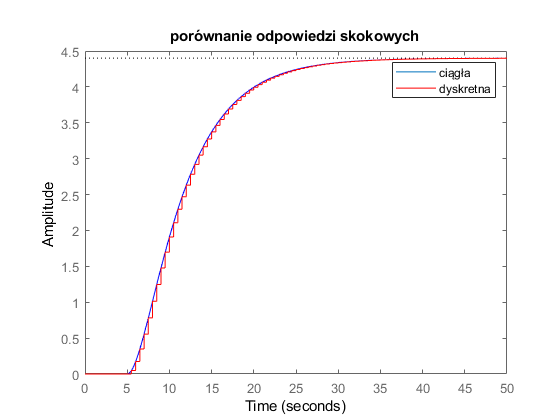

text='porównanie odpowiedzi skokowych';
step(Gs, 'b')
hold on
title(text)
step(Gz, 'r')
legend('ciągła', 'dyskretna')
print(text, '-djpeg', '-r500')
hold off

% zad 2 rownanie rozniocowe
%y(k) = 1.678y(k-1) - 0.6986y(k-2) + 0.0487u(k-1) -+ 0.0432u(k-2)
a1=-1.678;
a2=0.6986;
a3=0;
b1=0.0487;
b2=0.0432;
b3=0;
a=[a1 a2 a3]

a =    -1.6780    0.6986         0


b=[b1 b2 b3]

b =     0.0487    0.0432         0


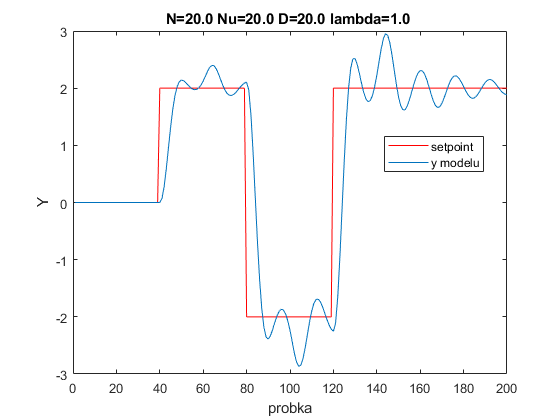

n_iter = 200;
% zad 3 regulator PID
D=20;    %horyzont dynamiki
lambda=1;
N=D;
Nu=D;


A = diag(ones(Nu,1)).*lambda;   %Nu*Nu
Psi = diag(ones(N,1)); %N*N
s = get_s(a, b, D);
Yzad_vec = vektor_zadanych(n_iter);
%Yzad_vec = skok_jednostkowy(n_iter).*2;
U=zeros(1,D);
Y_modelu = [0 0];
Y_modelu_global = zeros(n_iter,1);
U_global = zeros(n_iter, 1);

for k=1:size(Yzad_vec,1)
    Yzad=Yzad_vec(k);
    %Yk = aktualne wyjście modelu wyznaczone z rownania roznicowego
    Yk = b(1:2)*(U(1:2)') - a(1:2)*(Y_modelu(1:2)');
    Y_modelu_global(k)=Yk;
    Y_modelu=push_front(Y_modelu, Yk);
    Uk = DMC_out(Yzad, U, A, Psi, Yk, s, N, Nu, D);
    U_global(k) = Uk;
    U = push_front(U, Uk);
end
plot(Yzad_vec, 'r');
hold on
plot(Y_modelu_global)
legend('setpoint', 'y modelu', 'Location', 'best')
text=sprintf("N=%.1f Nu=%.1f D=%.1f lambda=%.1f ",N, Nu, D, lambda);
title(text)
xlabel('probka');
ylabel('Y');
%1probka->0.5s
hold off


error = sum((Y_modelu_global-Yzad_vec).^2)

error = 734.5944

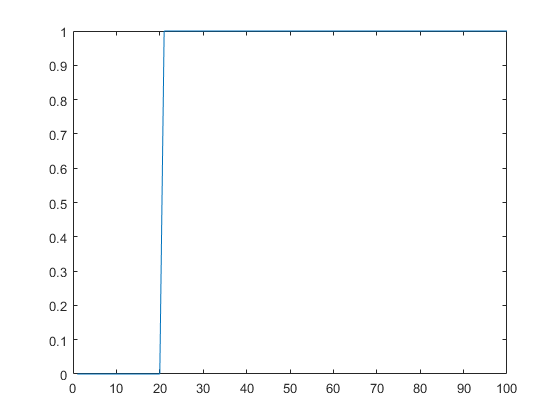

out = linspace(0,10);
out(out<=2)=0;
out(out>2)=1;

plot(out)





%PID tests
Kp=0.6;
Ki=0.5;
Kd=0;
Ti=1e20;
Td=0;
N=100;
%C = pidstd(Kp,Ti, Td, N);
C=pid(Kp, Ki, Kd);

%[C_pi,info] = pidtune(Gs, 'PI')
%C=tf([Kp], [1 0])
fe = feedback(C*Gs, -1);

Undefined function or variable 'Gs'.


x=linspace(0,20);
y=ones(size(x));
y(1)=0;
plot(x,y, 'r')
hold on
step(fe,20)
hold off






